% ============================================================
% MENG 3020 – FINAL PROJECT – PART C (White-box Modelling)
% Robot Arm-Link System Modeling & Identification
% ============================================================

%% -------------------------
% Equivalent mechanical parameters
Jeq = Jm + Js1 + JG1 + (Js2 + JG2 + m*L^2)/N^2;
Beq = Bm + B/N^2;

%% -------------------------
% Laplace variable
s = tf('s');

%% -------------------------
% Theoretical Transfer Function (arm angle / armature voltage)
G_theoretical = KT / ( s*((Ra + La*s)*(Jeq*s + Beq) + KT*Kb) );
present(G_theoretical)

th =
 
                0.8775
  ----------------------------------
  0.005654 s^3 + 1.214 s^2 + 3.932 s
 
Continuous-time transfer function.
Model Properties


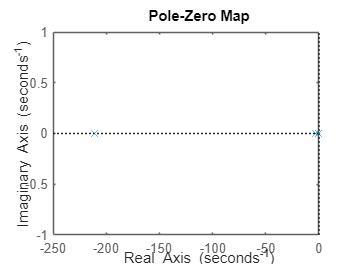


%% -------------------------
% Pole-Zero Map
pzmap(G_theoretical)

%% ------------------------- 
% DC Gain 
PCK_dc = dcgain(G_theoretical); 
disp(['DC Gain of Theoretical Model: '])

DC Gain of Theoretical Model: 


disp(PCK_dc)

   Inf



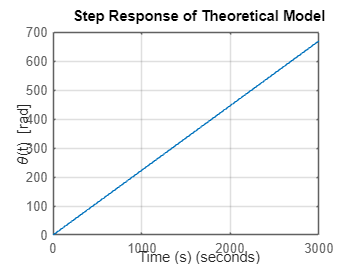

%% ------------------------- 
% Step Response 
figure; 
step(G_theoretical) 
grid on 
title('Step Response of Theoretical Model') 
xlabel('Time (s)') 
ylabel('\theta(t) [rad]')

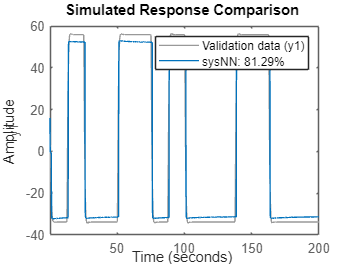

compare(data_NN, sysNN);

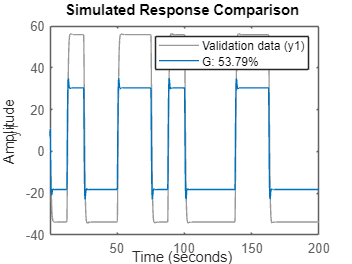


compare(data_NN, G);

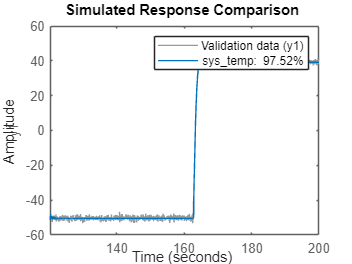


compare(dataVAL_High, sys_temp);

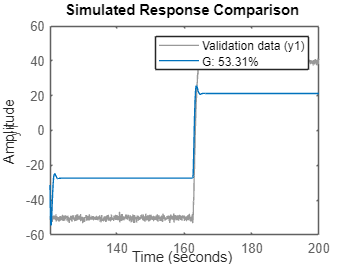

compare(dataVAL_High, G);


%% -------------------------
% End of Part C
